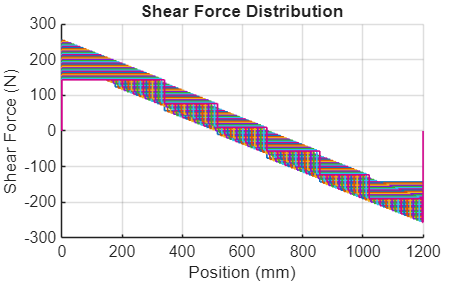

clearvars
close all
clc
clear
format long
clear figV
clear figM
clear; close all;

%% 0. Initialize Parameters
L = 1200;               % Length of bridge [mm]
n = 1200;               % Discretize into 1 mm segments
P = 400;                % Total weight of train [N]
x = linspace(0, L, n+1);% x-axis coordinates [mm]

%% 1. SFD, BMD under train loading
x_train = [52 228 392 568 732 908]; % Train axle locations [mm]
w_train = [1 1 1 1 1 1];            % Relative axle weights
P_train = w_train * P/sum(w_train); % Axle loads [N]

data_mult = 1;
units = "mm";
unit_multiplication = 1; % If you change the index spacing, update units instead.

% Figure for shear force diagrams
figV = figure;
grid on; hold on;
xlabel('Position ('+units+')');
ylabel('Shear Force (N)');
title('Shear Force Distribution');

% Figure for bending moment diagrams
% NOTE: this assumes 1 mm spacing (idx of 1). Changing idx randomly will break it.
figM = figure;
grid on; hold on;
set(gca,'YDir','reverse') % flips y so it goes - → +
xlabel('Position ('+units+')');
ylabel('Moment (Nmm)');
title('Bending Moment Diagram');

% Range of train offsets used for envelope 
i_vals = -51:10:292;           % same range you loop over
K = numel(i_vals);
YV = NaN(numel(x)+1, K);       % shear diagrams (for stairs: [0; V])
YM = NaN(numel(x),   K);       % moment diagrams M(x)
kk = 0;

% Defining the domain and the steps (10 mm)
for i = -51:10:292
    kk = kk + 1;
    location = x_train + i;    % shifted axle positions

    % Reactions from statics: sum M_A = 0
    sum_of_moment = 0;
    for idx = 1:6
        sum_of_moment = sum_of_moment + (L - location(idx)) * P_train(idx);
    end
    Ay = sum_of_moment / L;
    By = P - Ay;

    % Assemble point-load array F at each mm
    F = zeros(1,1201);                 
    idx = round(location);             
    val = P_train;
    idx = max(0, min(L, idx));         % clamp to [0, L] just in case
    F(idx + 1) = F(idx + 1) - val;     % downward axle loads
    F(1)   = Ay;                       % reaction at A
    F(end) = By;                       % reaction at B

    % Shear and moment via cumulative sums
    V = cumsum(F);                     % shear
    M = cumsum(V);                     % bending moment

    % Store for envelopes
    YV(:, kk) = [0; V(:)];             % matches stairs([0,x],[0,V])
    YM(:, kk) = M(:);

    % Plot this SFD
    figure(figV);                      % draw into the shear-figure
    stairs([0,x], [0,V], 'LineWidth', 1);

    % Plot this BMD
    figure(figM);                      % now the moment-figure
    plot(x, M, 'LineWidth', 1.5);
end

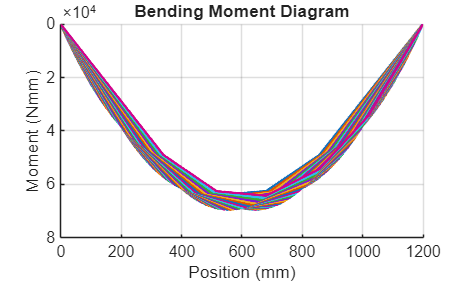



% Shear Force Envelope:
Xv   = [0, x];
Venv = max(YV, [], 2);
hold off

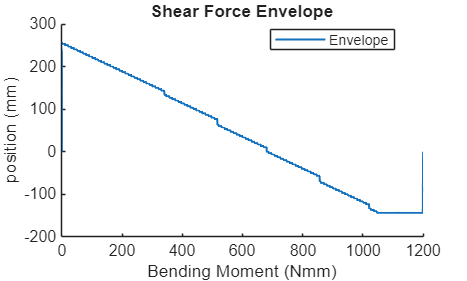

figure; hold on
plot(Xv, Venv, '-', 'LineWidth', 1.2);
legend({'Envelope'}, 'Location','best');
title("Shear Force Envelope")
xlabel("Bending Moment (Nmm)")
ylabel("position (mm)")

% Bending Moment Envelope:
Xm   = x(:);
Menv = max(YM, [], 2);
hold off

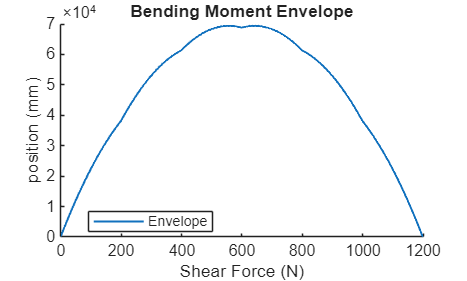

figure; hold on
plot(Xm, Menv, '-', 'LineWidth', 1.2);
legend({'Envelope'}, 'Location','best');
title("Bending Moment Envelope")
xlabel("Shear Force (N)")
ylabel("position (mm)")

%% 2. Define Bridge Parameters (while in the final design, the cross-sectional properties don't vary with depth) 
%          = xc,   b,  h, 

A1_param   = [0, 100, 1.27; 
           400, 100, 1.27; 
           800, 100, 1.27;
           L,   100, 1.27] 

A1_param = 1.0e+03 *

                   0   0.100000000000000   0.001270000000000
   0.400000000000000   0.100000000000000   0.001270000000000
   0.800000000000000   0.100000000000000   0.001270000000000
   1.200000000000000   0.100000000000000   0.001270000000000


A2_param   = [0, 6.27, 1.27; 
           400, 6.27, 1.27; 
           800, 6.27, 1.27;
           L,   6.27, 1.27] 

A2_param = 1.0e+03 *

                   0   0.006270000000000   0.001270000000000
   0.400000000000000   0.006270000000000   0.001270000000000
   0.800000000000000   0.006270000000000   0.001270000000000
   1.200000000000000   0.006270000000000   0.001270000000000


A3_param = A2_param

A3_param = 1.0e+03 *

                   0   0.006270000000000   0.001270000000000
   0.400000000000000   0.006270000000000   0.001270000000000
   0.800000000000000   0.006270000000000   0.001270000000000
   1.200000000000000   0.006270000000000   0.001270000000000


A4_param = [0,  1.27, 73.73; 
           400, 1.27, 73.73; 
           800, 1.27, 73.73;
           L,   1.27, 73.73] 

A4_param = 1.0e+03 *

                   0   0.001270000000000   0.073730000000000
   0.400000000000000   0.001270000000000   0.073730000000000
   0.800000000000000   0.001270000000000   0.073730000000000
   1.200000000000000   0.001270000000000   0.073730000000000


A5_param = A4_param

A5_param = 1.0e+03 *

                   0   0.001270000000000   0.073730000000000
   0.400000000000000   0.001270000000000   0.073730000000000
   0.800000000000000   0.001270000000000   0.073730000000000
   1.200000000000000   0.001270000000000   0.073730000000000


A6_param = [0,  77.46, 1.27; 
           400, 77.46, 1.27; 
           800, 77.46, 1.27;
           L,   77.46, 1.27] 

A6_param = 1.0e+03 *

                   0   0.077460000000000   0.001270000000000
   0.400000000000000   0.077460000000000   0.001270000000000
   0.800000000000000   0.077460000000000   0.001270000000000
   1.200000000000000   0.077460000000000   0.001270000000000



a = 400

a =    400



% Location, xx, of cross-section change 
xx=1

xx =      1


% Extracting user input assuming linear relationship 
b = [interp1(A1_param(:,1), A1_param(:,2), xx), interp1(A2_param(:,1), A2_param(:,2), xx), interp1(A3_param(:,1), A3_param(:,2), xx), interp1(A4_param(:,1), A4_param(:,2), xx), interp1(A5_param(:,1), A5_param(:,2), xx), interp1(A6_param(:,1), A6_param(:,2), xx)]

b = 1.0e+02 *

   1.000000000000000   0.062700000000000   0.062700000000000   0.012700000000000   0.012700000000000   0.774600000000000


h = [interp1(A1_param(:,1), A1_param(:,3), xx), interp1(A2_param(:,1), A2_param(:,3), xx), interp1(A3_param(:,1), A3_param(:,3), xx), interp1(A4_param(:,1), A4_param(:,3), xx), interp1(A5_param(:,1), A5_param(:,3), xx), interp1(A6_param(:,1), A6_param(:,3), xx)]

h =    1.270000000000000   1.270000000000000   1.270000000000000  73.730000000000004  73.730000000000004   1.270000000000000



material_spent = (round(sum(b.*h.*1200)/1.27)) * 1.0417; %note; extra needed for diaphragms 
available = 813*1016;

% y: absolute y from top of each param to bottom of cross section
y = [h(1)+h(2)+h(4), h(2)+h(4), h(2)+h(4), h(4), h(4), h(6)]   

y =   76.270000000000010  75.000000000000000  75.000000000000000  73.730000000000004  73.730000000000004   1.270000000000000



Area_param = b.* h

Area_param = 1.0e+02 *

   1.270000000000000   0.079629000000000   0.079629000000000   0.936371000000000   0.936371000000000   0.983742000000000


% ybar_param: from centroid of each param to bottom of cross section
ybar_param = y - 0.5 * h

ybar_param =   75.635000000000005  74.364999999999995  74.364999999999995  36.865000000000002  36.865000000000002   0.635000000000000


% ybar: location of centroidal axis from the bottom 
ybar = sum(Area_param.* ybar_param) / sum(Area_param)

ybar =   41.431094351923193


% ybar_param: location of centroidal axis of each param from neutral axis 
d_param = abs(ybar_param - ybar)

d_param =   34.203905648076812  32.933905648076802  32.933905648076802   4.566094351923191   4.566094351923191  40.796094351923195


ybot = ybar

ybot =   41.431094351923193


ytop = h(1)+h(2)+h(4)-ybar

ytop =   34.838905648076818


% I 
I1 = sum(b.*h.^3 / 12)

I1 =      8.486940726893170e+04


I2 = sum((d_param.^2).* Area_param)

I2 =      3.334828017304919e+05


I = sum(I1) + sum(I2)

I =      4.183522089994236e+05



% Q at centroidal axes     
Qcent = d_param(6) * Area_param(6) + 2 * (ybar/2) * ybar * b(4)

Qcent =      6.193283330576374e+03


% Q at glue location 
Qglue = d_param(1) * Area_param(1)

Qglue =      4.343896017305755e+03


%% 4. Calculate Applied Stress
%Compute maxima of envelopes
Mmax = max(abs(Menv))

Mmax =      6.944233333333449e+04


Vmax = max(abs(Venv))

Vmax =      2.570000000000001e+02


S_top  =  Mmax * ytop / I    

S_top =    5.782914125799855


S_bot  =  Mmax * ybot / I

S_bot =    6.877152319171921


T_cent =  Vmax * Qcent / (I * 2 * b(4))   

T_cent =    1.497884369077272


T_glue =  Vmax * Qglue / (I * 2 * b(2))    

T_glue =    0.212800645523802



%% 5. Material and Thin Plate Buckling Capacities; unit: MPa
% Material Properties:
S_tens  = 30;
S_comp  = 6;
T_max   = 4;
T_gmax  = 2;
E       = 4000; 
mu      = 0.2; 
% flange mid-buckling
t1 = h(1);   
b1 = b(6) + (b(4) / 2) + (b(5) / 2);
S_buck1 = ((4 * pi^2 * E) / (12 * (1 - mu^2))) * (t1 / b1)^2;
% flange sides-buckling
t2 = t1;
b2 = (b(1) - b1) / 2;
S_buck2 = ((0.425 * pi^2 * E) / (12 * (1 - mu^2))) * (t2 / b2)^2

S_buck2 =   20.769624320288862


% Web buckling
t3 = b(4);
b3 = ytop - h(1); 
S_buck3 = (6 * pi^2 * E) / (12 * (1 - mu^2)) * (t3 / b3)^2;
% Local shear buckling
t4 = t3;
h4 = h(2) + h(4)   

h4 =     75


a = a  

a =    400


T_buck  = (5 * pi^2 * E) / (12 * (1 - mu^2)) * ((t4 / h4)^2 + (t4 / a)^2)

T_buck =    5.085903149965052








%% 6. FOS 
FOS_tens = S_tens / abs(S_bot)

FOS_tens =    4.362270691077598


FOS_comp = S_comp / abs(S_top) 

FOS_comp =    1.037539183442417


FOS_shear = T_max / abs(T_cent)

FOS_shear =    2.670433100563086


FOS_glue = T_gmax / abs(T_glue)  

FOS_glue =    9.398467730570378


FOS_buck1 = S_buck1 / abs(S_top)

FOS_buck1 =    0.616804373922657


FOS_buck2 = S_buck2 / abs(S_top)

FOS_buck2 =    3.591549842946379


FOS_buck3 = S_buck3 / abs(S_top) 

FOS_buck3 =    5.089145174636823


FOS_buckV = T_buck / abs(T_cent) 

FOS_buckV =    3.395391029481185


## 7. Min FOS and the failure load Pfail

%% 9. Plot stress demand vs stress capacity (constant capacity lines)

Mmax = max(abs(Menv));   
Vmax = max(abs(Venv));  

%Compute constant failure modes from maximum demand possible
Mf_tens    = FOS_tens  * Mmax;
Mf_comp    = FOS_comp  * Mmax;
Mf_buck1   = FOS_buck1 * Mmax;
Mf_buck2   = FOS_buck2 * Mmax;
Mf_buck3   = FOS_buck3 * Mmax;

Vf_shear   = FOS_shear * Vmax;
Vf_glue    = FOS_glue  * Vmax;
Vf_buckV   = FOS_buckV * Vmax;

minFOS = min([FOS_tens, FOS_comp, FOS_shear, FOS_glue, FOS_buck1, FOS_buck2, FOS_buck3, FOS_buckV])

minFOS =    0.616804373922657


Pf = minFOS * P  % max train load that cause failure

Pf =      2.467217495690630e+02


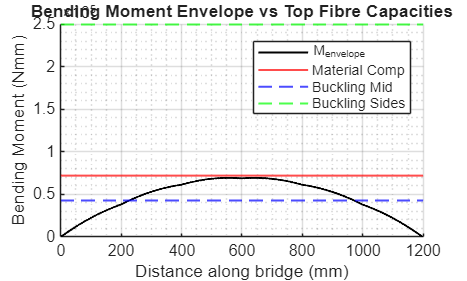


set(0, 'DefaultFigureColor', 'w');  
set(0, 'DefaultAxesColor',   'w');  
set(0, 'DefaultFigureInvertHardcopy', 'off');  

% (1) Bending: Top fibre (compression) vs material + buckling
figure;
hold on; grid on; grid minor;
plot(Xm, Menv, 'k', 'LineWidth', 1.2);          
yline(Mf_comp, 'r',  'LineWidth', 1.2);   % compression failure
yline(Mf_buck1, 'b--','LineWidth', 1.2);  % flange mid-buckling failure
yline(Mf_buck2, 'g--','LineWidth', 1.2);  % flange sides-buckling failure
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nmm)');
title('Bending Moment Envelope vs Top Fibre Capacities');
legend('M_{envelope}','Material Comp','Buckling Mid','Buckling Sides','Location','best');

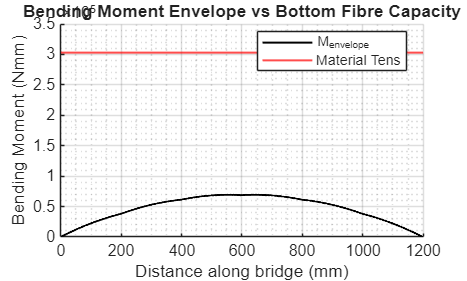


% (2) Bending: Bottom fibre (tension) vs material capacity
figure;
hold on; grid on; grid minor;
plot(Xm, Menv, 'k', 'LineWidth', 1.2);           
yline(Mf_tens, 'r',  'LineWidth', 1.2);  % tension failure
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nmm)');
title('Bending Moment Envelope vs Bottom Fibre Capacity');
legend('M_{envelope}','Material Tens','Location','best');

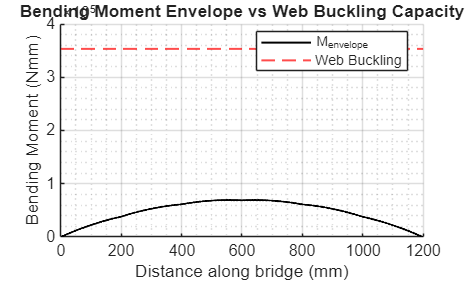


% (3) Bending: Web buckling
figure;
hold on; grid on; grid minor;
plot(Xm, Menv, 'k', 'LineWidth', 1.2);            
yline(Mf_buck3,     'r--','LineWidth', 1.2);  % web buckling failure
xlabel('Distance along bridge (mm)');
ylabel('Bending Moment (Nmm)');
title('Bending Moment Envelope vs Web Buckling Capacity');
legend('M_{envelope}','Web Buckling','Location','best');

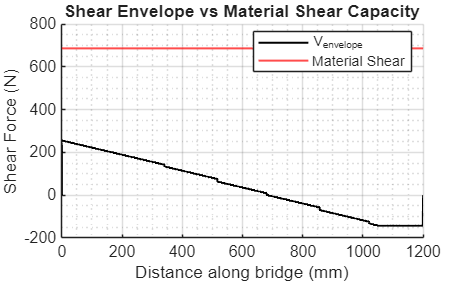


% (4) Shear: Material shear at centroid
figure;
hold on; grid on; grid minor;
plot(Xv, Venv, 'k', 'LineWidth', 1.2);            
yline(Vf_shear,     'r',  'LineWidth', 1.2);  % material shear failure
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');
title('Shear Envelope vs Material Shear Capacity');
legend('V_{envelope}','Material Shear','Location','best');

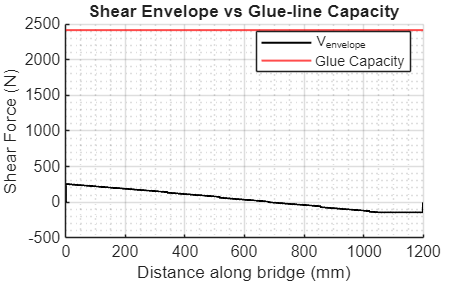


% (5) Shear: Glue-line
figure;
hold on; grid on; grid minor;
plot(Xv, Venv, 'k', 'LineWidth', 1.2);            
yline(Vf_glue, 'r',  'LineWidth', 1.2);  % glue shear failure
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');
title('Shear Envelope vs Glue-line Capacity');
legend('V_{envelope}','Glue Capacity','Location','best');

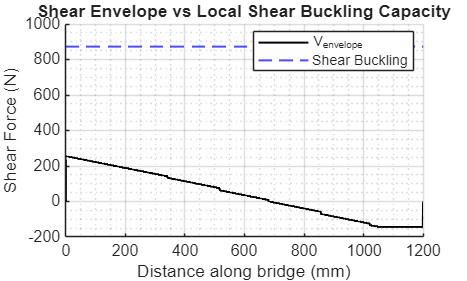


% (6) Shear: Local shear buckling
figure;
hold on; grid on; grid minor;
plot(Xv, Venv, 'k', 'LineWidth', 1.2);           
yline(Vf_buckV, 'b--','LineWidth', 1.2);  % shear buckling failure
xlabel('Distance along bridge (mm)');
ylabel('Shear Force (N)');
title('Shear Envelope vs Local Shear Buckling Capacity');
legend('V_{envelope}','Shear Buckling','Location','best');